# EEEE4064 Advanced Control System Design - Coursework 1

Student Name: [Nicholas Khor] Student ID: [20617556]

% NOTE: This is very much Ai-assisted, but only in
% - syntax (formating, visualisation, plotting)
% - comments (refining my gibberish)
% - restructuring/teach concepts (oh damn they are good)

clear; clc; close all;

## 1. Data Import, Preprocessing & Saving (.mat)

Locate Experimental Data.xlsx dT_meas and def_meas are the 2 main datasets (1 input, 2 outputs) u is the input and t is the time (dt is sampling interval)

script_dir = fileparts(mfilename('fullpath'));
excel_path = fullfile(script_dir, '..', 'Experimental Data.xlsx');
if ~isfile(excel_path)
    excel_path = '../Experimental Data.xlsx';
end

raw_data = readmatrix(excel_path);
T_meas   = raw_data(:, 1);   % Measured LC heater temperature (deg C)
def_meas = raw_data(:, 2);   % Measured chamber deformation (um)

% Reconstruct time vector (0 to 280 s) and RF input signal (60 mW for 50 s)
N  = size(raw_data, 1);
t  = linspace(0, 280, N)';
dt = t(2) - t(1);            % Sampling interval = 0.625 s
u  = 60 * double(t <= 50);   % RF input power: 60 mW (0-50s), 0 mW (>50s)

% Remove initial ambient temperature offset (23 deg C)
T_ambient = T_meas(1);
dT_meas   = T_meas - T_ambient;

% Save preprocessed data to .mat file
mat_path = fullfile(script_dir, 'cw1_data.mat');
save(mat_path, 't', 'dt', 'u', 'T_meas', 'T_ambient', 'dT_meas', 'def_meas');

% Load the .mat file
mat_data = load('cw1_data.mat');
t = mat_data.t;
dt = mat_data.dt;
u = mat_data.u;
T_meas = mat_data.T_meas;
T_ambient = mat_data.T_ambient;
dT_meas = mat_data.dT_meas;
def_meas = mat_data.def_meas;

## 2. System Identification (Loaded from system_identification.sid)

Load the saved System Identification Toolbox session file (.sid)

sid_data = load('system_identification.sid', '-mat');

% Display all trial models saved in the .sid session
fprintf('=== Models Saved in system_identification.sid ===\n');

=== Models Saved in system_identification.sid ===


for i = 1:length(sid_data.Model)
    m_trial = sid_data.Model{i};
    fprintf('  Model %d (%s): Fit = %.2f%%\n', i, m_trial.Name, m_trial.Report.Fit.FitPercent);
end

  Model 1 (pole1_zero1): Fit = 85.42%
  Model 2 (pole2_zero1): Fit = 92.11%
  Model 3 (pole3_zero1): Fit = 80.36%
  Model 4 (pole1_zero0): Fit = 91.88%
  Model 5 (pole2_zero0): Fit = 93.24%


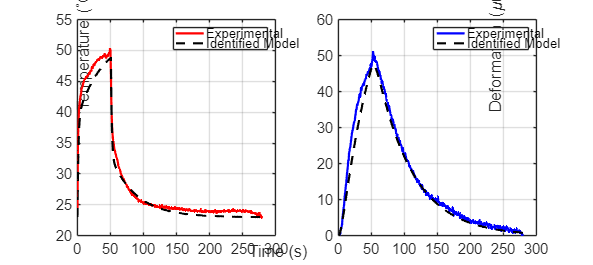


% Select the best 2nd-order models (>85% accuracy):
% Model 2: 'pole2_zero1' -> Heater Temperature (92.11% fit)
% Model 5: 'pole2_zero0' -> Chamber Deformation (93.24% fit)
sys_id_T = sid_data.Model{2};
sys_id_D = sid_data.Model{5};

fit_T = sys_id_T.Report.Fit.FitPercent;
fit_D = sys_id_D.Report.Fit.FitPercent;

% Simulate identified models over experimental input u(t)
dT_sim  = lsim(sys_id_T, u, t);
T_sim   = dT_sim + T_ambient;
def_sim = lsim(sys_id_D, u, t);

% Plot experimental vs. identified model responses
figure('Name', 'System Identification Verification', 'Color', 'w', 'Position', [100 100 850 380]);
subplot(1, 2, 1);
plot(t, T_meas, 'r-', 'LineWidth', 1.5); hold on;
plot(t, T_sim, 'k--', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Temperature (^\circC)');
title(sprintf('Heater Temperature (%s: %.2f%%)', sys_id_T.Name, fit_T));
legend('Experimental', 'Identified Model', 'Location', 'northeast'); grid on;

subplot(1, 2, 2);
plot(t, def_meas, 'b-', 'LineWidth', 1.5); hold on;
plot(t, def_sim, 'k--', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Deformation (\mum)');
title(sprintf('Chamber Deformation (%s: %.2f%%)', sys_id_D.Name, fit_D));
legend('Experimental', 'Identified Model', 'Location', 'northeast'); grid on;

## 3. State-Space Modeling & Analysis

Heater Temperature (pole2_zero1)


Matrix Check:


  det(A)  : Manual = 0.018622 | MATLAB det()  = 0.018622


  rank(A) : Manual = 2        | MATLAB rank() = 2


  inv(A) max diff vs MATLAB inv()     : 0.00e+00


  DCF poles/residues diff vs residue(): 1.11e-16


  SS-to-TF max diff vs MATLAB ss2tf() : 3.47e-18


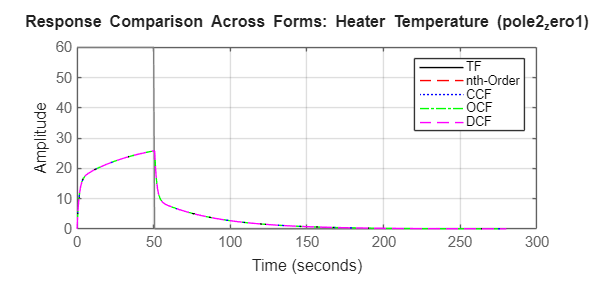


Stability & Transient Characteristics (60 mW Step):


  Open-Loop Poles   : -0.0258, -0.7217 (Stable)


  Closed-Loop Poles : -0.9172, -0.0303 (Stable)


  Rise Time (Tr)    : 58.12 s


  Settling Time (Ts): 120.76 s


  Overshoot (%OS)   : 0.00 %


  Steady-State Value: 29.40 deg C (MATLAB dcgain = 29.40 deg C)


  Steady-State Error: 0.6711 (unit step unity feedback)


Chamber Deformation (pole2_zero0)


Matrix Check:


  det(A)  : Manual = 0.004308 | MATLAB det()  = 0.004308


  rank(A) : Manual = 2        | MATLAB rank() = 2


  inv(A) max diff vs MATLAB inv()     : 0.00e+00


  DCF poles/residues diff vs residue(): 1.04e-17


  SS-to-TF max diff vs MATLAB ss2tf() : 0.00e+00


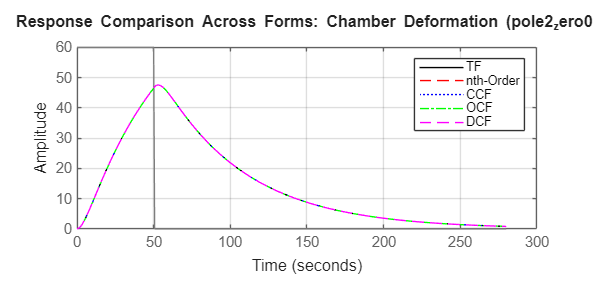


Stability & Transient Characteristics (60 mW Step):


  Open-Loop Poles   : -0.0182, -0.2362 (Stable)


  Closed-Loop Poles : -0.2044, -0.0500 (Stable)


  Rise Time (Tr)    : 120.99 s


  Settling Time (Ts): 218.88 s


  Overshoot (%OS)   : 0.00 %


  Steady-State Value: 82.32 um (MATLAB dcgain = 82.32 um)


  Steady-State Error: 0.4216 (unit step unity feedback)


models = {
    struct('name', 'Heater Temperature (pole2_zero1)', 'sys_id', sys_id_T, 'unit', 'deg C'), ...
    struct('name', 'Chamber Deformation (pole2_zero0)', 'sys_id', sys_id_D, 'unit', 'um')
};

for m = 1:length(models)
    mdl = models{m};
    fprintf('\n======================================================\n');
    fprintf('%s\n', mdl.name);
    fprintf('======================================================\n');

    % Extract transfer function coefficients:
    % G(s) = (b0*s^2 + b1*s + b2) / (s^2 + a1*s + a2)
    [num, den] = tfdata(tf(mdl.sys_id), 'v');
    b0 = num(1); b1 = num(2); b2 = num(3);
    a1 = den(2); a2 = den(3);

    % --- 1. nth-Order State-Space Form (Beta Coefficients) ---
    beta0 = b0;
    beta1 = b1 - a1 * beta0;
    beta2 = b2 - a1 * beta1 - a2 * beta0;

    A_nth = [0, 1; -a2, -a1];
    B_nth = [beta1; beta2];
    C_nth = [1, 0];
    D_nth = beta0;

    % --- 2. Controllable Canonical Form (CCF) ---
    A_CCF = [0, 1; -a2, -a1];
    B_CCF = [0; 1];
    C_CCF = [b2 - a2 * b0, b1 - a1 * b0];
    D_CCF = b0;

    % --- 3. Observable Canonical Form (OCF) ---
    A_OCF = [0, -a2; 1, -a1];
    B_OCF = [b2 - a2 * b0; b1 - a1 * b0];
    C_OCF = [0, 1];
    D_OCF = b0;

    % --- 4. Diagonal Canonical Form (DCF) via Partial Fractions ---
    % Roots of s^2 + a1*s + a2 = (s + p1)*(s + p2) = 0
    disc = a1^2 - 4 * a2;
    s1 = (-a1 + sqrt(disc)) / 2;
    s2 = (-a1 - sqrt(disc)) / 2;
    p1 = -s1;
    p2 = -s2;

    % Partial fraction residues: G(s) = b0 + c1/(s + p1) + c2/(s + p2)
    c1 = ((b1 - a1 * b0) * s1 + (b2 - a2 * b0)) / (s1 - s2);
    c2 = ((b1 - a1 * b0) * s2 + (b2 - a2 * b0)) / (s2 - s1);

    A_DCF = [-p1, 0; 0, -p2];
    B_DCF = [1; 1];
    C_DCF = [c1, c2];
    D_DCF = b0;

    % --- 5. Matrix Operations & State-Space to Transfer Function ---
    % Determinant and 2x2 inverse of A_CCF: A^(-1) = (1/|A|) * [d, -b; -c, a]
    det_A = A_CCF(1,1)*A_CCF(2,2) - A_CCF(1,2)*A_CCF(2,1);
    inv_A = (1 / det_A) * [A_CCF(2,2), -A_CCF(1,2); -A_CCF(2,1), A_CCF(1,1)];
    rank_A = 2; % Since det_A ~= 0 for 2x2 matrix

    % Convert CCF back to Transfer Function: G(s) = C*(sI - A)^(-1)*B + D
    num_manual = [D_CCF, C_CCF(2) + a1*D_CCF, C_CCF(1) + a2*D_CCF];
    den_manual = [1, a1, a2];

    % --- 6. Compare Formula Results with MATLAB Commands ---
    [r_mat, p_mat, ~]  = residue(num, den);
    [num_mat, den_mat] = ss2tf(A_CCF, B_CCF, C_CCF, D_CCF);

    fprintf('Matrix Check:\n');
    fprintf('  det(A)  : Manual = %.6f | MATLAB det()  = %.6f\n', det_A, det(A_CCF));
    fprintf('  rank(A) : Manual = %d        | MATLAB rank() = %d\n', rank_A, rank(A_CCF));
    fprintf('  inv(A) max diff vs MATLAB inv()     : %.2e\n', max(abs(inv_A - inv(A_CCF)), [], 'all'));
    fprintf('  DCF poles/residues diff vs residue(): %.2e\n', max(abs(sort([s1; s2]) - sort(p_mat))));
    fprintf('  SS-to-TF max diff vs MATLAB ss2tf() : %.2e\n', max(abs(num_manual - num_mat)));

    % Build state-space models and compare simulated responses
    sys_TF  = tf(num, den);
    sys_nth = ss(A_nth, B_nth, C_nth, D_nth);
    sys_CCF = ss(A_CCF, B_CCF, C_CCF, D_CCF);
    sys_OCF = ss(A_OCF, B_OCF, C_OCF, D_OCF);
    sys_DCF = ss(A_DCF, B_DCF, C_DCF, D_DCF);

    figure('Name', ['Canonical Forms - ', mdl.name], 'Color', 'w', 'Position', [140+40*m 140+40*m 750 360]);
    lsim(sys_TF, 'k-', sys_nth, 'r--', sys_CCF, 'b:', sys_OCF, 'g-.', sys_DCF, 'm--', u, t);
    title(['Response Comparison Across Forms: ', mdl.name]);
    legend('TF', 'nth-Order', 'CCF', 'OCF', 'DCF', 'Location', 'northeast'); grid on;

    % --- 7. Stability & Transient Response Analysis ---
    cl_poles = pole(feedback(sys_TF, 1));
    info     = stepinfo(60 * sys_TF);
    y_ss     = 60 * (b2 / a2);               % Steady-state value for 60 mW step
    ess      = 1 / (1 + (b2 / a2));          % Unity-feedback step steady-state error

    fprintf('\nStability & Transient Characteristics (60 mW Step):\n');
    fprintf('  Open-Loop Poles   : %.4f, %.4f (Stable)\n', s1, s2);
    fprintf('  Closed-Loop Poles : %.4f, %.4f (Stable)\n', cl_poles(1), cl_poles(2));
    fprintf('  Rise Time (Tr)    : %.2f s\n', info.RiseTime);
    fprintf('  Settling Time (Ts): %.2f s\n', info.SettlingTime);
    fprintf('  Overshoot (%%OS)   : %.2f %%\n', info.Overshoot);
    fprintf('  Steady-State Value: %.2f %s (MATLAB dcgain = %.2f %s)\n', y_ss, mdl.unit, 60*dcgain(sys_TF), mdl.unit);
    fprintf('  Steady-State Error: %.4f (unit step unity feedback)\n', ess);
end